## Exploratory Group Assignment

#### Amanda Chang, Dokyun Kim, Jun Park

close all;
clear all;

A) Plot images for 3 different frequencies of sine or cosine waves. Plot the Fourier transforms of the 3 images.

Sine Wave (Frequency: 25.00 Hz)

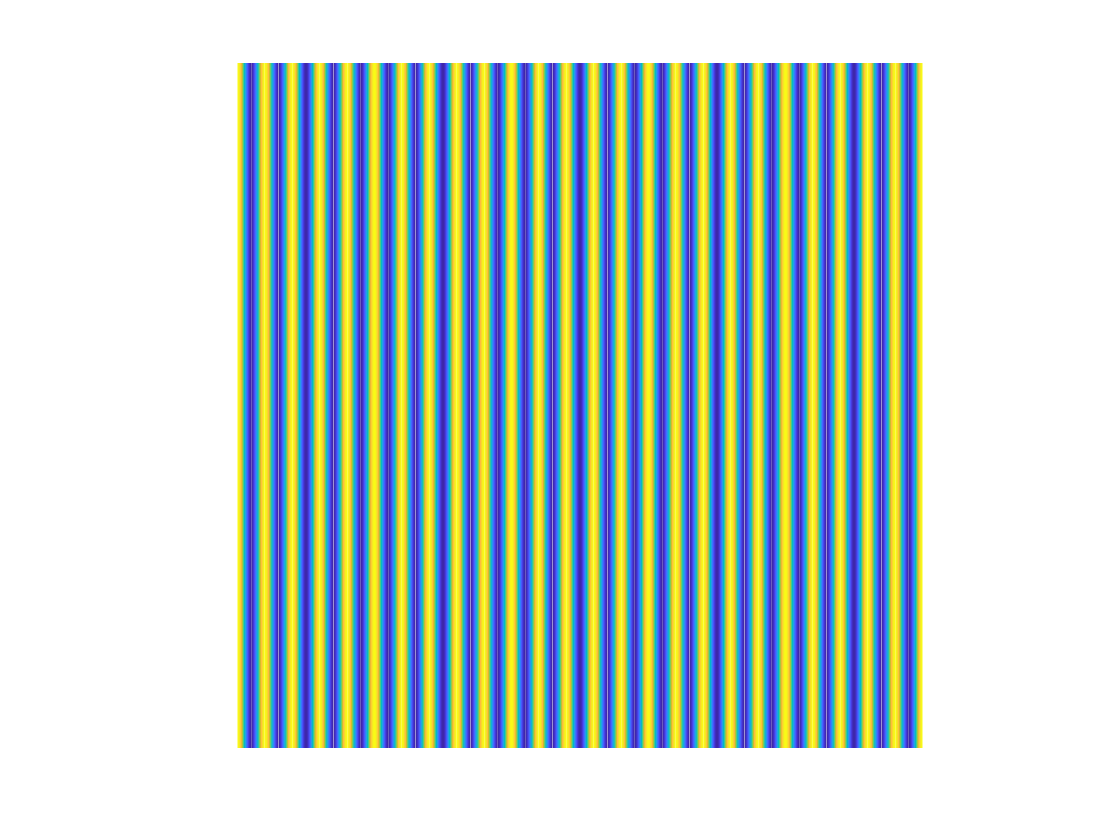

FFT of Sine Wave (Frequency: 25.00 Hz)

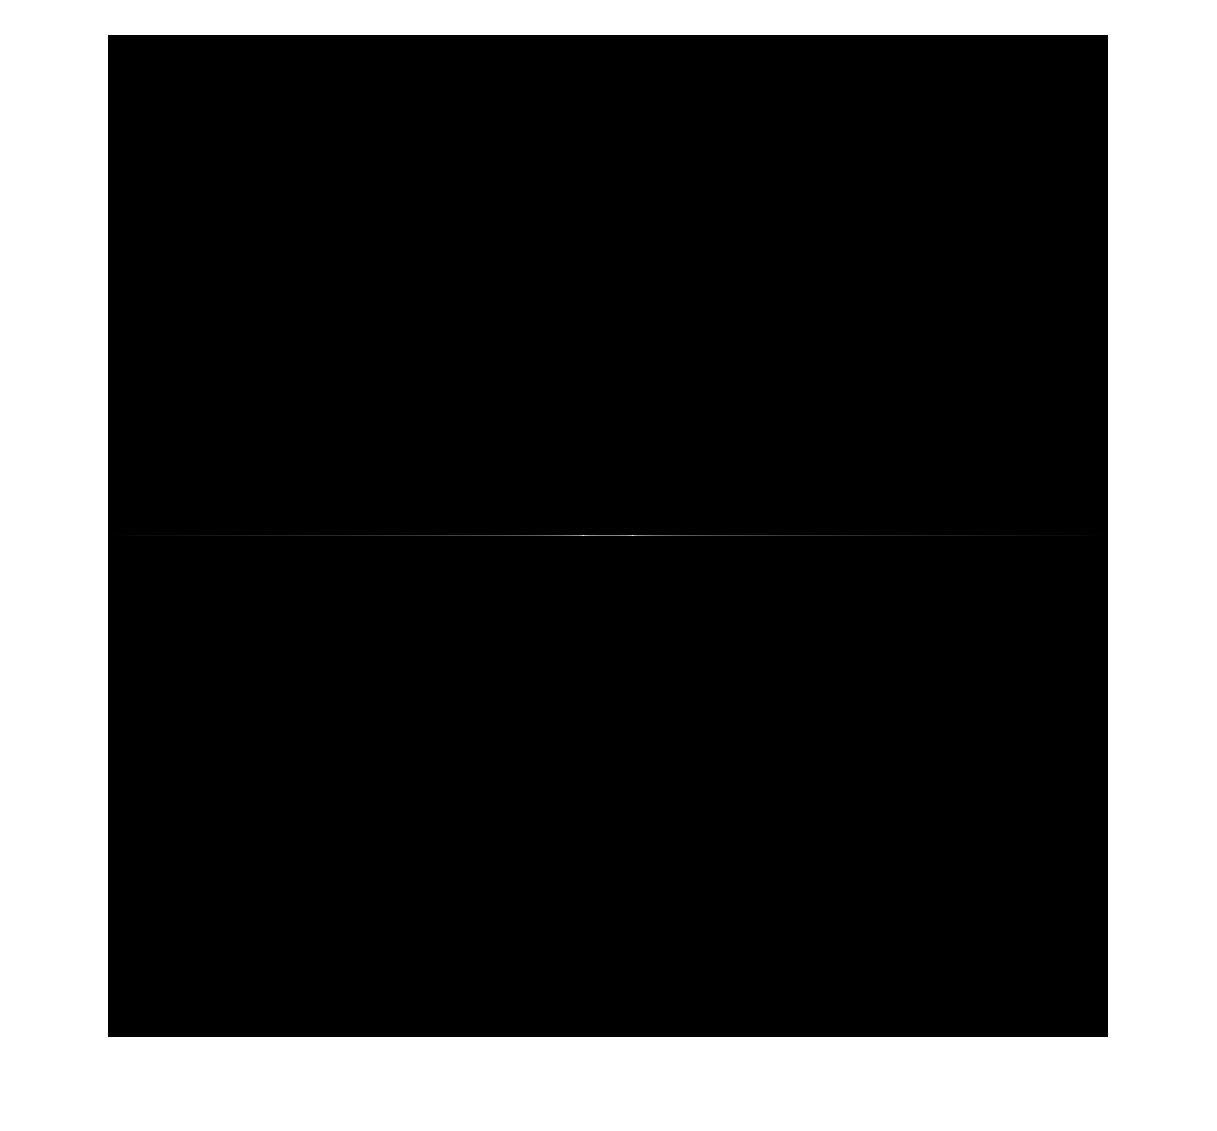

freq1 = 25;
freq2 = 75;
freq3 = 125;
sine_grate(freq1);

Sine Wave (Frequency: 75.00 Hz)

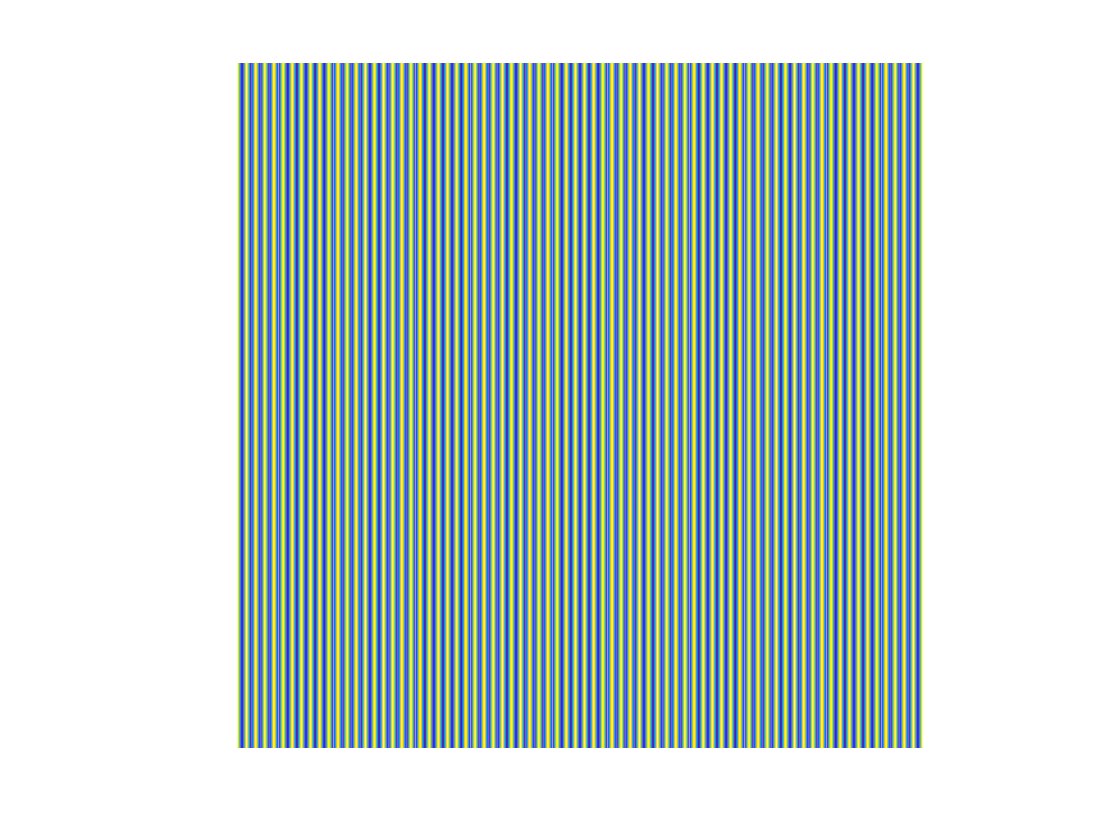

FFT of Sine Wave (Frequency: 75.00 Hz)

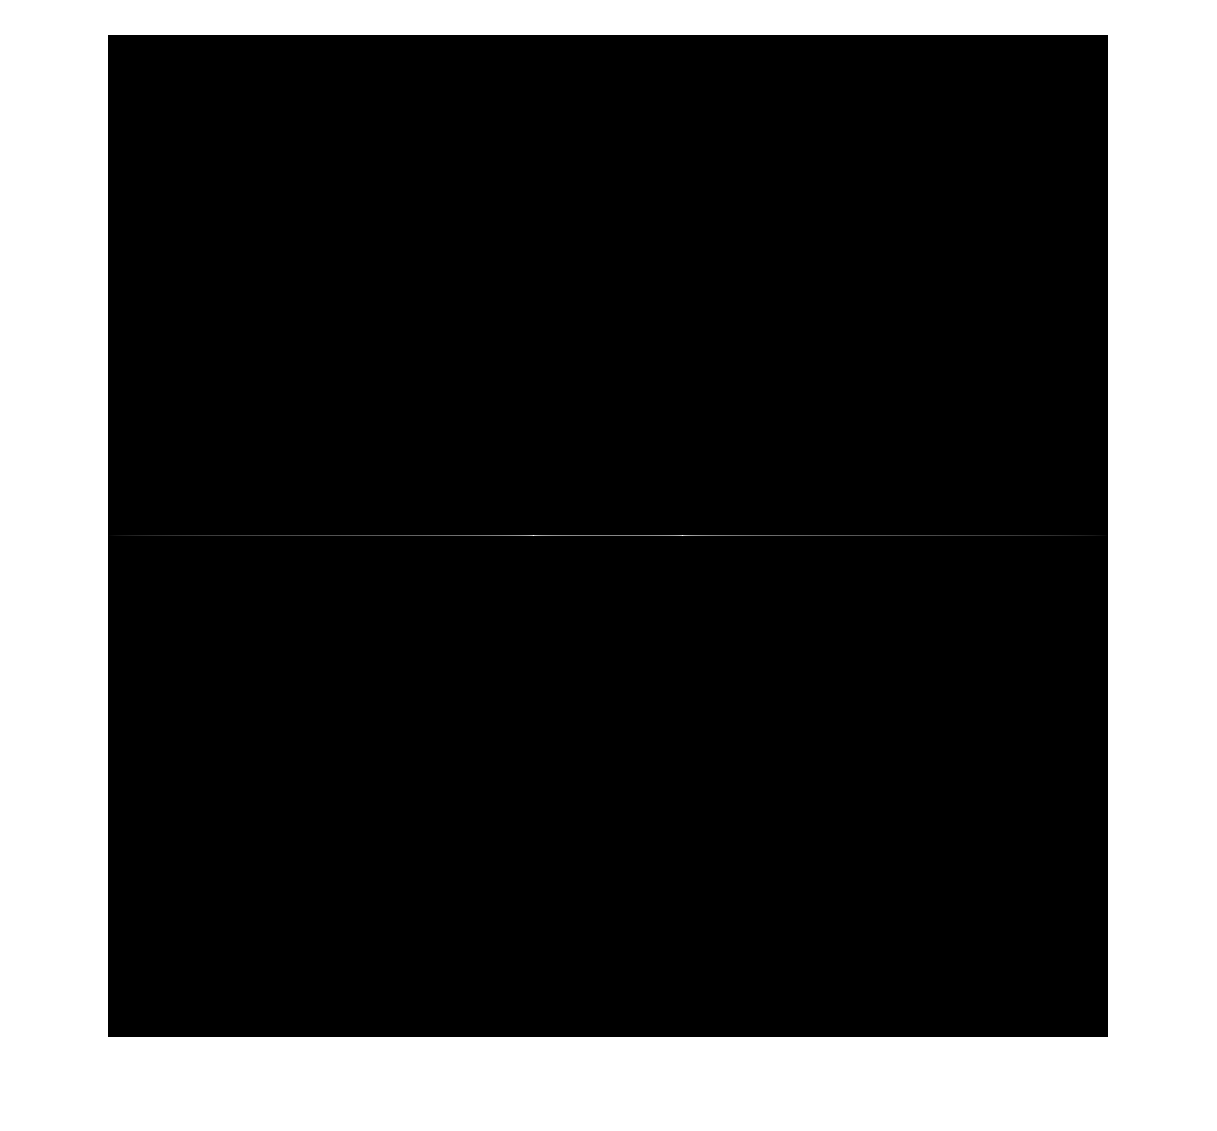

sine_grate(freq2);

Sine Wave (Frequency: 125.00 Hz)

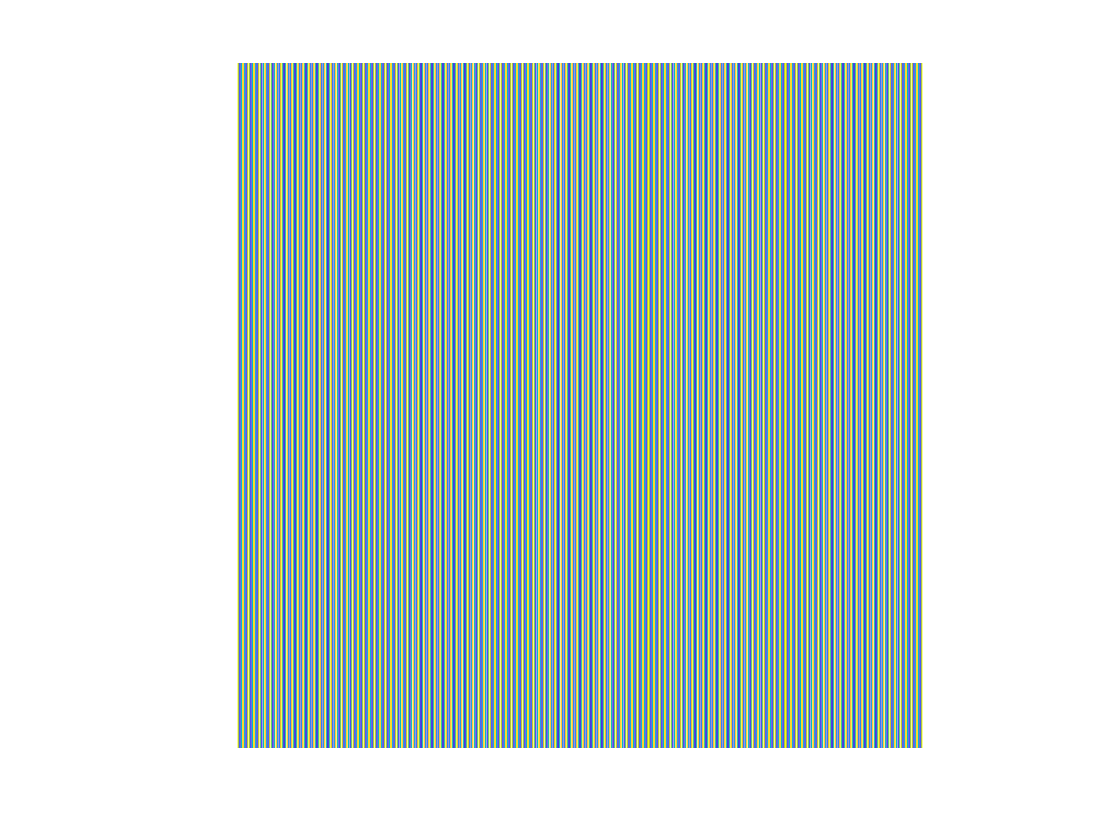

FFT of Sine Wave (Frequency: 125.00 Hz)

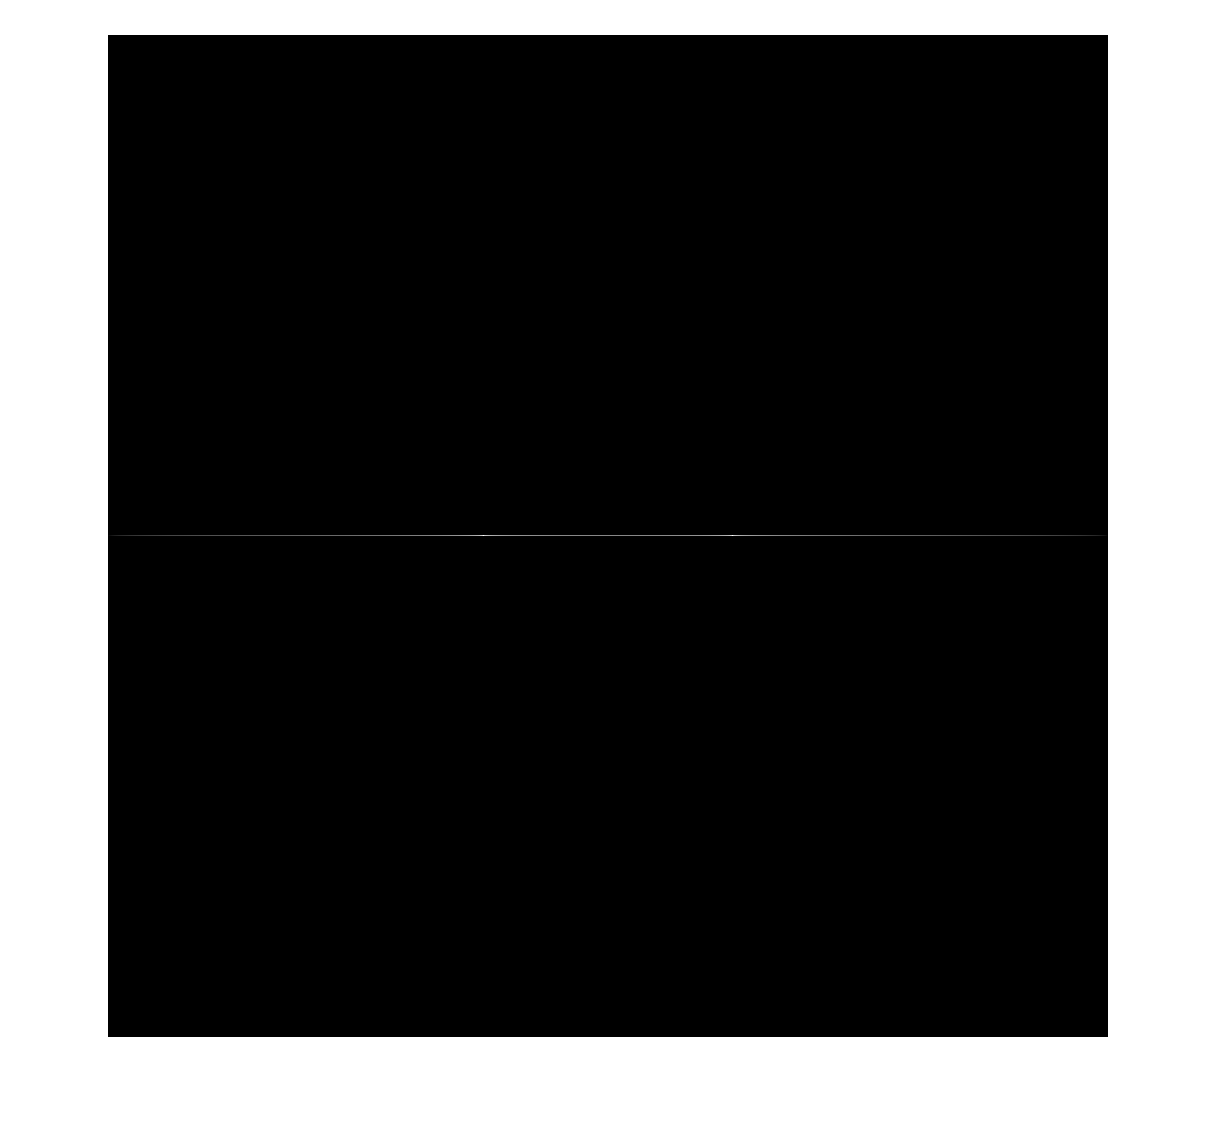

sine_grate(freq3);

B) Create these three shapes in MATLAB or Python, find their Fourier transforms, and verify whether the Fourier transforms shown on the right are correct.

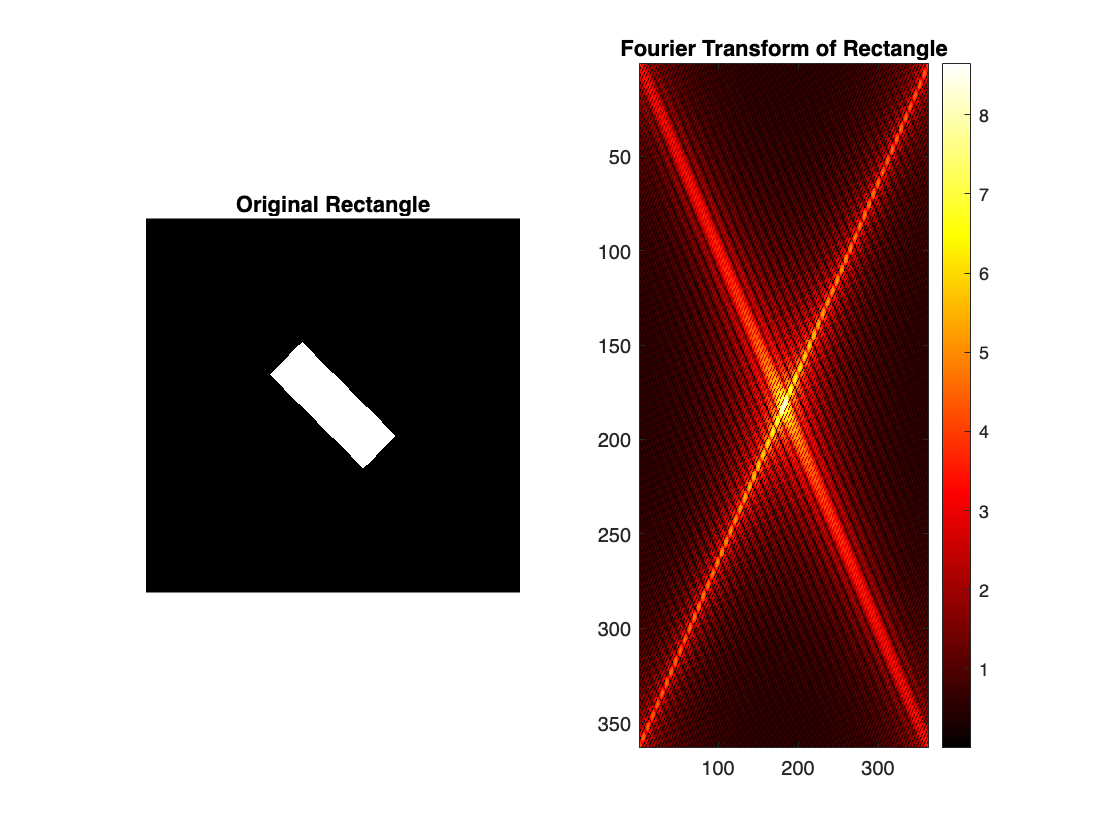

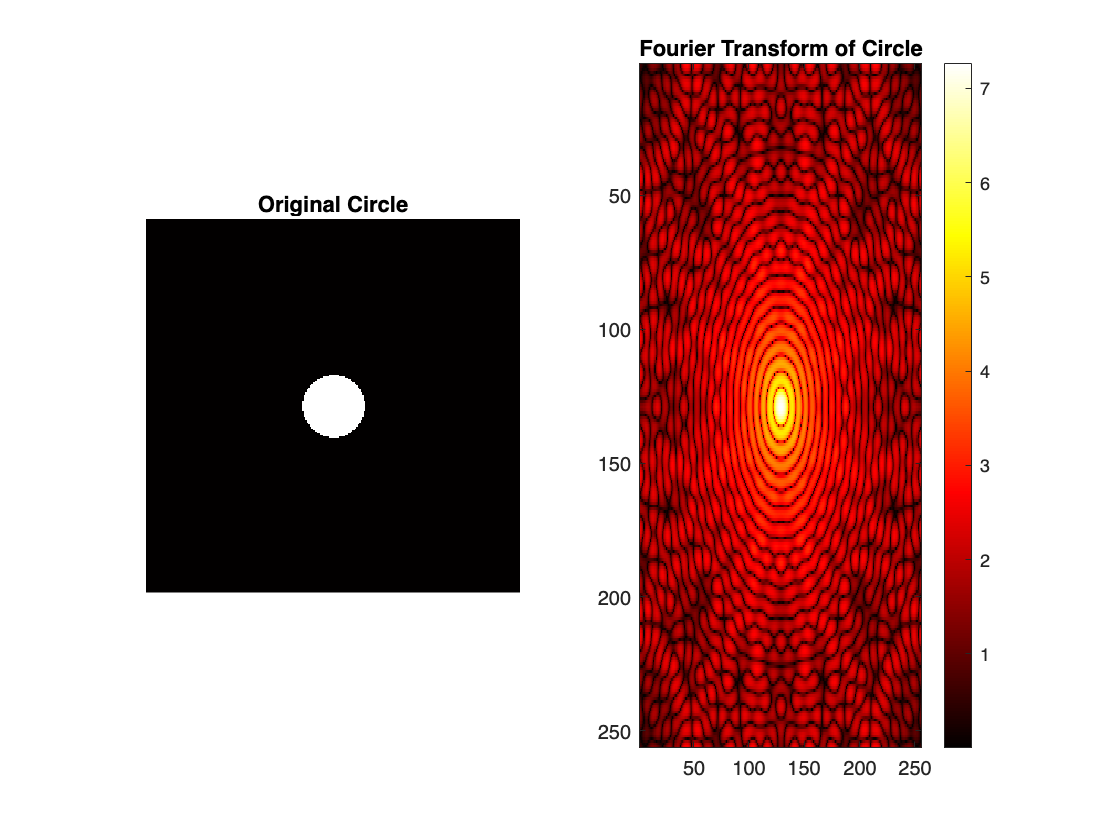

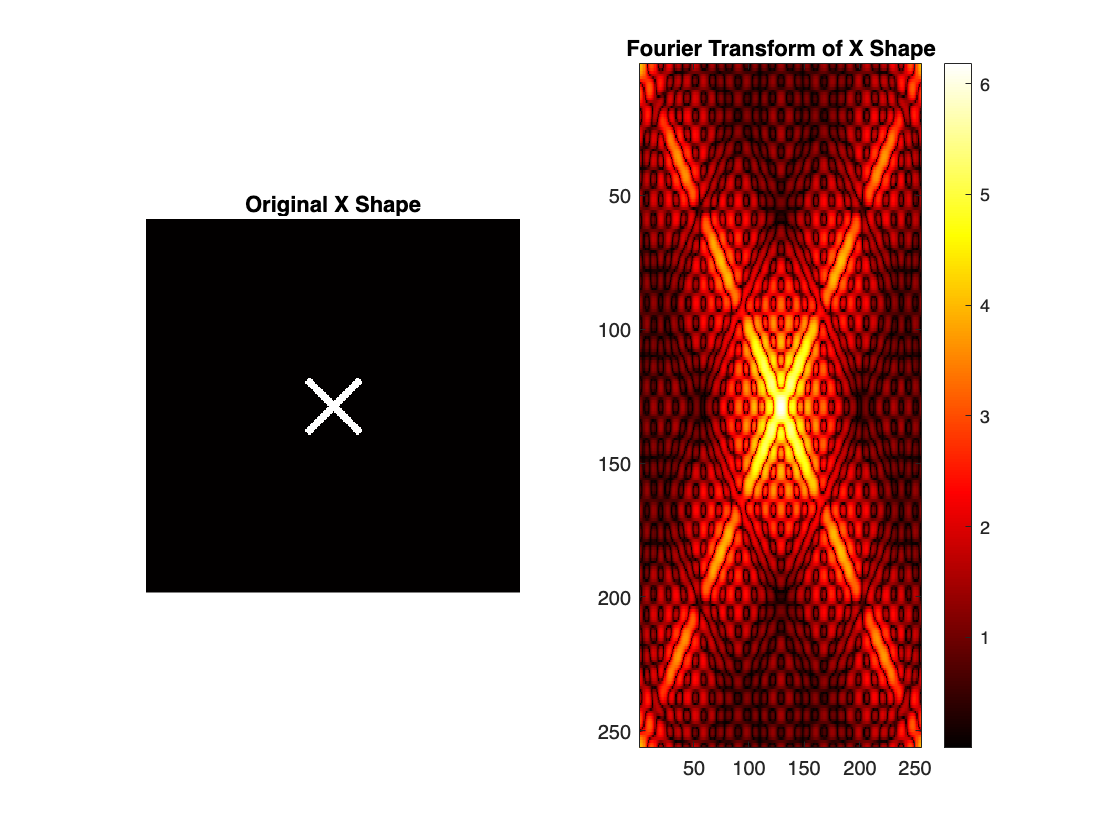

gridSize = 256;
[X, Y] = meshgrid(-gridSize/2:gridSize/2-1, -gridSize/2:gridSize/2-1);

% Rectangle
rect = zeros(gridSize);
rectHeight = round(gridSize / 2);
rectWidth = round(gridSize / 6);
centerY = round(gridSize / 2);
centerX = round(gridSize / 2);
yStart = round(centerY - rectHeight/2);
yEnd = round(centerY + rectHeight/2);
xStart = round(centerX - rectWidth/2);
xEnd = round(centerX + rectWidth/2);
rect(yStart:yEnd, xStart:xEnd) = 1;
rect = imrotate(rect, 45);

% Circle
radius = gridSize / 12;
circle = sqrt(X.^2 + Y.^2) <= radius;

% X Shape
X_shape = zeros(gridSize);
thickness = 3;
diagonalLength = gridSize / 10;
X_shape(abs(X - Y) <= thickness & sqrt(X.^2 + Y.^2) <= diagonalLength) = 1; 
X_shape(abs(X + Y) <= thickness & sqrt(X.^2 + Y.^2) <= diagonalLength) = 1; 

shapes = {rect, circle, X_shape};
shapeNames = {'Rectangle', 'Circle', 'X Shape'};

for k = 1:length(shapes)
    figure;
    shape = shapes{k};
    
    % Compute Fourier Transform
    F = fftshift(fft2(shape));
    
    % Magnitude spectrum (Adding 1 for clearer Visuals)
    magnitudeF = log(1 + abs(F));
    
    subplot(1, 2, 1);
    imshow(shape, []);
    title(['Original ', shapeNames{k}]);

    subplot(1, 2, 2);
    imagesc(magnitudeF);
    title(['Fourier Transform of ', shapeNames{k}]);
    colorbar;
    colormap("hot");
end

C) Use an image of your choice, plot its Fourier transform. Comment on whether interpreting the Fourier Transform was intuitive.